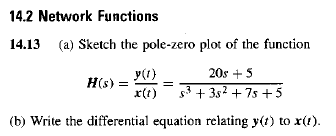

clc, clear, close all
format short g

**a)** definimos la función de transferencia con la funcion tf del toolbox de matlab control system, y usamos la funcion pzmap para trazar un plano (real,imaginario) y visualizar los polos y zeros.

h = tf([20 5],[1 3 7 5]) %funcion de trasferencia

h =
 
        20 s + 5
  ---------------------
  s^3 + 3 s^2 + 7 s + 5
 
Continuous-time transfer function.



z = zero(h)

z =         -0.25


p = pole(h)

p =            -1 +          2i
           -1 -          2i
           -1 +          0i


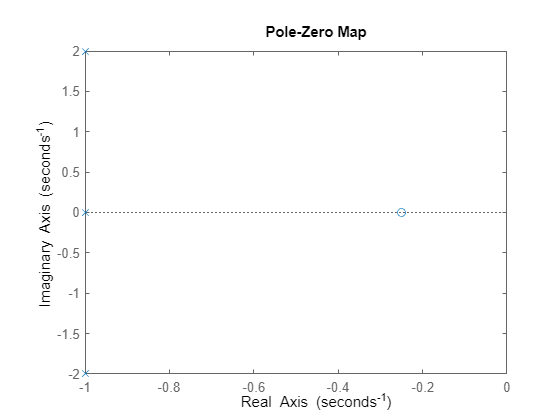

pzmap(h)

**b) **Como tenemos la funcion de transferencia, y sabemos que por la relacion *y(t)/x(t)*, si los igualamos vemos que los terminos del numerador corresponden a *x(t)* y los del denominador a *y(t), *por lo que aplicamos la transformada inversa de laplace para expresarla en terminos de ecuacion diferencial:

syms s x y

num_h = (20*s+5) %numerador de la tf

$$num\_h = 20\,s+5$$

den_h = (s^3+3*s^2+7*s+5) %denominador de la tf

$$den\_h = s^{3}+3\,s^{2}+7\,s+5$$

ilaplace(num_h,x) %en terminos de eds

$$ans = 5\,\delta (x)+20\,\delta^{\prime }(x)$$

ilaplace(den_h,y) %en terminos de eds

$$ans = 5\,\delta (y)+7\,\delta^{\prime }(y)+3\,\delta^{\prime \prime }(y)+\delta^{\prime \prime \prime }(y)$$